# Evalución de las capacidades de robot Scara

## Resumen

A continuacion dr  expone la evaluación exhaustiva de las capacidades cinemáticas, dinámicas y operacionales de un robot manipulador SCARA de tres grados de libertad (3 GDL) mediante simulación numérica en el entorno de MATLAB Live Editor. El objetivo primordial de la investigación es planificar, validar y comparar el comportamiento del robot al ejecutar una trayectoria diagonal suave desde una postura inicial en el plano cartesiano$P_{\text{in}} = (0.3, 0.3, 0)
$ hasta una posición final extrema $P_ {\text{fin}} = (0.8, 0.8, 0)
$ sobre el primer cuadrante.

Para garantizar transiciones de movimiento armónicas y anular los tirones mecánicos (*jerk*) en los extremos temporales $t = 0\text{ s}
$ y $t = 10\text{ s}
$, se implementó un perfil de parametrización temporal basado en un polinomio de interpolación de quinto orden. El análisis se abordó desde dos enfoques metodológicos complementarios:

- Planeación en el Espacio Articular: Donde se determinaron analíticamente las posturas de frontera mediante cinemática inversa estática (configuración codo arriba) para interpolar directamente las coordenadas de las juntas de manera independiente.

- Planeación en el Espacio de Trabajo: Donde se forzó al efector final a describir una línea recta cartesiana perfecta en tiempo real, resolviendo la cinemática de velocidades y la aproximación a zonas singulares a través del formalismo del Jacobiano Geométrico Diferencial y el Índice de Manipulabilidad de Yoshikawa.

Finalmente, el estudio incorpora el modelado analítico avanzado de la Dinámica Inversa empleando un esquema de sustitución simbólica por variables auxiliares generalizadas. A través de este modelo, se calcularon de forma continua los perfiles de torque requeridos por los actuadores y las curvas de potencia mecánica instantánea absorbida. Los resultados numéricos y gráficos obtenidos sirven como criterio técnico de diseño para dimensionar los sistemas de accionamiento del robot y validar la viabilidad física de la tarea antes de su despliegue en entornos de control real como ROS 2.

## 1. Defición de la tarea

El robot SCARA de 3 grados de libertad (GDL) debe trasladar su efector final describiendo un lugar geométrico de línea recta cartesiana perfecta. Para evaluar de forma exhaustiva sus capacidades dinámicas y cinemáticas en múltiples ejes de forma simultánea, la trayectoria se programa de manera diagonal, desplazándose desde una coordenada (X) positiva, y de una altura (Y) baja a una más elevada. Sobre el primer cuadrante.

% =========================================================================
% SECCIÓN 1: DEFINICIÓN DE LOS PUNTOS DE LA TRAYECTORIA DIAGONAL
% =========================================================================
% Pose inicial (Abajo a la izquierda en el plano cartesiano)
x_in = 0.3;  % Posición inicial en el eje X (metros)
y_in = 0.3; % Posición inicial en el eje Y (metros)
theta_in = 0;  % Orientación inicial del efector final (radianes)
% Pose final (Arriba a la derecha en el plano cartesiano)
x_fin = 0.8;  % Posición final en el eje X (metros)
y_fin = 0.8;  % Posición final en el eje Y (metros)
theta_fin = 0;  % Orientación final (mantenida constante en 0 rad)

### 1 Definición de la tarea en el espacio de las juntas

Para llevar a cabo la planificación de movimientos asegurando un seguimiento de trayectoria estrictamente rectilíneo en el espacio operacional, se implementa el método geométrico de cinemática inversa. Este formalismo matemático permite transformar las coordenadas cartesianas deseadas $(X, Y)$ y la orientación del efector final en las variables articulares correspondientes del robot SCARA, denotadas como $\theta_1
$ (junta de la base), $\theta_2
$ (junta del codo) y $\theta_3$ (junta de la muñeca).

% =========================================================================
% CÁLCULO DE LA CINEMÁTICA INVERSA PARA LA PRIMERA POSTURA (CONFIGURACIÓN INICIAL)
% =========================================================================

% --- DEFINICIÓN DE LOS PARÁMETROS GEOMÉTRICOS DEL ROBOT SCARA ---
L1 = 0.5; % Longitud del primer eslabón
L2 = 0.5; % Longitud del segundo eslabón
L3 = 0.3; % Longitud del tercer eslabón

% --- PLANTEAMIENTO DE LA SOLUCIÓN: DESACOPLAMIENTO DE LA MUÑECA ---
% Se resta la proyección del tercer eslabón (L3) respecto a la orientación inicial
% para encontrar las coordenadas (x_3, y_3) del centro de la articulación de la muñeca.

x_3 = x_in - L3*cos(theta_in);
y_3 = y_in - L3*sin(theta_in);

% --- SOLUCIÓN POR EL MÉTODO GEOMÉTRICO (ARTICULACIÓN DEL CODO) ---
% Se aplica el Teorema de los Cosenos sobre el triángulo formado por L1 y L2 
% para calcular el ángulo de flexión requerido en la segunda junta (theta_2_in).

theta_2_in = acos((x_3^2+y_3^2-L1^2-L2^2)/(2*L1*L2))

theta_2_in = 2.5322


beta = atan2(y_3,x_3);

psi = acos((x_3^2+y_3^2+L1^2-L2^2)/(2*L1*sqrt(x_3^2+y_3^2)));

% theta_1_in = beta + psi

 theta_1_in = beta - psi

theta_1_in = 0.3047


% theta_1_in = beta - psi


theta_3_in = theta_in -theta_1_in - theta_2_in

theta_3_in = -2.8369

 Interpretación Física y Geométrica

Al analizar la combinación de estos tres ángulos, podemos deducir exactamente cómo se está posicionando físicamente tu robot SCARA en el espacio:

1. Configuración de "Codo Arriba" (*Elbow-Up*)

El valor de `theta_2_in` es positivo y bastante cerrado $145.08^\circ$. Esto significa que el segundo eslabón se flexiona fuertemente hacia adentro (hacia la izquierda del primer eslabón si lo miras desde la base). Geométricamente, el robot adopta una postura "recogida" o arqueada para poder ubicar la muñeca muy cerca del origen, ya que el punto $(0.3, 0.3)$ está a una distancia radial corta de solo $\approx 0.424$ metros de la base.

2. Compensación de la Muñeca (`theta_3_in`)

Dado que tu condición cartesiana inicial exige estrictamente que la herramienta apunte hacia adelante de forma completamente horizontal en el eje X $\theta_{\text{in}} = 0$, la tercera articulación tiene que hacer un giro drástico en sentido horario $-162.54^\circ$. Esto compensa perfectamente la rotación de la base$17.46^\circ$  y la flexión del codo $145.08^\circ$:


$$\theta = 17.46^\circ + 145.08^\circ - 162.54^\circ = 0^\circ$$


% =========================================================================
% CÁLCULO DE LA CINEMÁTICA INVERSA PARA LA POSTURA FINAL (DESTINO)
% =========================================================================

% --- DESACOPLAMIENTO CINEMÁTICO DE LA MUÑECA (PUNTO FINAL) ---
% Se resta el efecto del tercer eslabón (L3) a las coordenadas finales (x_fin, y_fin)
% para aislar la posición geométrica del centro de la articulación de la muñeca.

x_3 = x_fin - L3*cos(theta_fin);
y_3 = y_fin - L3*sin(theta_fin);

% --- SOLUCIÓN GEOMÉTRICA PARA LA ARTICULACIÓN DEL CODO ---
% Aplicación de la Ley de Cosenos para determinar el ángulo de apertura final 
% de la segunda junta (theta_2_fin) en radianes.

theta_2_fin = acos((x_3^2+y_3^2-L1^2-L2^2)/(2*L1*L2))

theta_2_fin = 0.6761

% --- SOLUCIÓN GEOMÉTRICA PARA LA ARTICULACIÓN DE LA BASE ---
% 'beta' representa el ángulo polar (en radianes) desde el origen de la base
% del robot hasta las coordenadas calculadas de la muñeca (x_3, y_3).
beta = atan2(y_3,x_3);

psi = acos((x_3^2+y_3^2+L1^2-L2^2)/(2*L1*sqrt(x_3^2+y_3^2)));

% theta_1_fin = beta + psi

theta_1_fin = beta - psi

theta_1_fin = 0.6741

% --- SOLUCIÓN PARA LA ORIENTACIÓN DE LA HERRAMIENTA ---
% Como la orientación total respecto al mundo es la suma de las tres juntas
% (theta = th1 + th2 + th3), se despeja la tercera junta restando las anteriores.
theta_3_fin = theta_fin -theta_1_fin - theta_2_fin

theta_3_fin = -1.3503

Modelado de la Cinemática Inversa (Postura Final)

El cálculo de la postura final del manipulador en las coordenadas de destino$P_{\text{fin}} = (0.8, 0.8, 0)
$ se rige bajo los mismos principios geométricos de desacoplamiento aplicados en el origen. Sin embargo, para la determinación del ángulo de la base ($\theta_{1\text{\_fin}}
$, el algoritmo evalúa de forma secuencial el ángulo polar global de la muñeca ($\beta
$) y el ángulo de compensación trigonométrico ($\psi_1
$).

Al consolidar la ecuación fundamental $\theta_1 = \beta - \psi_1
$, se impone de manera matemática la restricción cinemática de Codo Arriba (*Elbow-Up*). Este criterio asegura la consistencia estructural del manipulador durante todo el trayecto dinámico, previniendo que el brazo intente realizar una conmutación de postura abrupta o físicamente imposible en el aire mientras se traslada hacia el punto de destino.

Interpretación Física y Comportamiento Crítico

1. El brazo está casi completamente estirado

A diferencia de la posición inicial donde el "codo" estaba muy flexionado $145^{\circ }$, aquí `theta_2_fin` cae drásticamente a solo $38.73^{\circ }$. El brazo se abre casi por completo en línea recta para poder alcanzar la coordenada $(0.8, 0.8)$.

2. Validación de la coincidencia numérica (Curiosidad geométrica)

Note que $\theta_1fin$ $(0.6741)$ y $\theta_2fin$ (0.6761) son prácticamente idénticos. Esto ocurre porque el punto de la muñeca $(x_3, y_3)$ se encuentra exactamente sobre la diagonal simétrica del plano cartesiano $(X = Y)$. Al tener eslabones de igual longitud $(L_1 = L_2 = 0.5)$, el robot forma un triángulo isósceles perfecto, distribuyendo el giro de manera equitativa entre la base y el codo.

3. Confirmación de Orientación

La suma geométrica vuelve a ser perfecta para garantizar que la herramienta no rote respecto al suelo:


$$\(\theta =38.62^{\circ }+38.73^{\circ }-77.35^{\circ }=0^{\circ }\)$$


## 2.Plateamiento de una trayectoria en el espacio de las juntas del robot

2.1. Descripción Conceptual

La planeación en el espacio articular consiste en la generación de perfiles de movimiento aplicados de forma directa e independiente sobre los actuadores o coordenadas generalizadas del robot $(q_1, q_2, q_3)
$.  A diferencia del enfoque cartesiano, este método no modela ni restringe la trayectoria geométrica que describe el efector final en el espacio físico. En su lugar, el algoritmo transforma únicamente las posturas extremas (origen y destino) a sus equivalentes angulares mediante cinemática inversa estática y, posteriormente, interpola los perfiles de movimiento para cada motor a lo largo del tiempo.

En este desarrollo, el objetivo es realizar una transición suave de las variables de junta desde sus valores iniciales calculados  $\Theta_{\text{in}} = (\theta_{1\text{\_in}}, \theta_{2\text{\_in}}, \theta_{3\text{\_in}})
$hasta las consignas de destino $\Theta_{\text{fin}} = (\theta_{1\text{\_fin}}, \theta_{2\text{\_fin}}, \theta_{3\text{\_fin}})
$, correspondientes a los puntos cartesianos $(0.3, 0.3, 0)
$ y $(0.8, 0.8, 0)
$ respectivamente.

2.2. Metodología y Flujo Algorítmico

El diseño del perfil de movimiento en el dominio articular se fundamenta en un esquema descentralizado que opera bajo los siguientes criterios algorítmicos:

- Resolución Estática de Fronteras: Antes de iniciar el movimiento temporal, se ejecuta la cinemática inversa del manipulador únicamente dos veces: una para determinar la configuración articular de partida y otra para la de llegada. Esto exime al procesador de realizar cálculos analíticos complejos durante el desplazamiento dinámico del robot.

- Parametrización por Polinomio de Quinto Orden: Para garantizar un movimiento armónico, se aplica de manera independiente a cada una de las tres juntas un polinomio de interpolación de quinto grado. La evolución temporal de la posición de la junta \(j\) en el instante \(t\) se rige por la ecuación: $q_j(t) = q_{j\text{\_in}} + \left[ \frac{10}{t_f^3}t^3 - \frac{15}{t_f^4}t^4 + \frac{6}{t_f^5}t^5 \right] \cdot (q_{j\text{\_fin}} - q_{j\text{\_in}})
$  Donde $t_f = 10\text{ s}
$representa el tiempo total de la tarea. Al imponer analíticamente condiciones de frontera con velocidad y aceleración nulas en       (t = 0) y (t = t_f), se eliminan las discontinuidades en los extremos del perfil, lo que mitiga los impactos mecánicos y prolonga la vida útil de los servomotores.

2.3. Evaluación Técnica del Enfoque

- Ventajas: Presenta una eficiencia computacional óptima, ideal para sistemas embebidos o controladores en tiempo real con recursos limitados, ya que evita resolver funciones trigonométricas inversas de forma iterativa dentro del bucle principal. Adicionalmente, al planificar directamente sobre las juntas, se garantiza que los motores operen dentro de perfiles de velocidad suaves y predecibles, eliminando el riesgo de exigir movimientos físicamente imposibles o velocidades infinitas asociadas a singularidades cartesianas.

- Limitaciones y Riesgos: La principal desventaja radica en la pérdida de control sobre el camino recorrido por el efector final en el espacio físico. Debido a la no linealidad del modelo cinemático directo del robot SCARA, la punta del manipulador describirá una trayectoria curva no lineal (arqueada) en el aire para trasladarse entre los puntos. Este comportamiento limita severamente su uso en aplicaciones industriales que requieran precisión geométrica en el trayecto o en entornos con alta densidad de obstáculos donde el riesgo de colisión sea elevado.

Definición de la trayectoria


$$q =q_i +\lambda \left(t\right)\left(q_{\mathrm{fin}} -q_{\mathrm{in}} \right)$$


% =========================================================================
% PLANTEAMIENTO DE UNA TRAYECTORIA EN EL ESPACIO DE LAS JUNTAS DEL ROBOT
% =========================================================================

% Definición del tiempo final de la trayectoria (10 segundos)
tf = 10;

% Bucle para calcular los puntos intermedios (itera 11 veces, de i=1 a 11)
for i=1:tf+1

     % Calcula el tiempo actual basado en el índice de la iteración (de 0 a 10s)
    t = i-1; % Increment time for the next iteration
     % --- Junta 1: Interpolación con polinomio de 5to grado ---
    theta_1_P(i) = theta_1_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_1_fin-theta_1_in);
    % --- Junta 2: Interpolación con polinomio de 5to grado ---
    theta_2_P(i) = theta_2_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_2_fin-theta_2_in);
    % --- Junta 3: Interpolación con polinomio de 5to grado ---
    theta_3_P(i) = theta_3_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_3_fin-theta_3_in);

end % Fin del bucle de interpolación

theta_1_P

theta_1_P =     0.3047    0.3079    0.3261    0.3649    0.4220    0.4894    0.5569    0.6139    0.6527    0.6710    0.6741


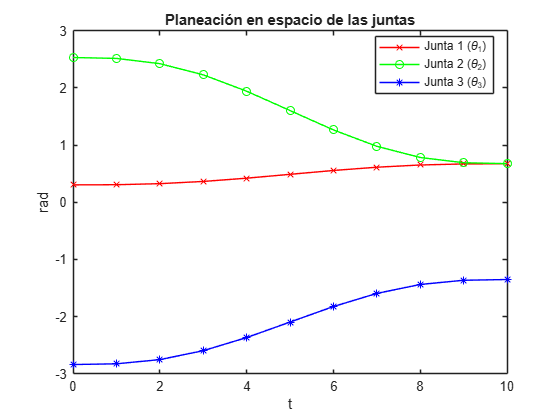

tsim = 0:1:tf; % Creación del vector de tiempo de muestreo para el eje X de las gráficas
figure;

plot(tsim, theta_1_P, 'r-x'); % Grafica la trayectoria de la Junta 1 en color rojo con marcadores 'x'
hold on;
plot(tsim, theta_2_P, 'g-o'); % Grafica la trayectoria de la Junta 2 en color verde con marcadores 'o'
plot(tsim, theta_3_P, 'b-*'); % Grafica la trayectoria de la Junta 3 en color azul con marcadores '*'

hold off;

legend('Junta 1 (\theta_1)', 'Junta 2 (\theta_2)', 'Junta 3 (\theta_3)', 'Location', 'best');
title("Planeación en espacio de las juntas")
xlabel("t")
ylabel("rad")

Esta gráfica representa visualmente el comportamiento de los motores del robot a lo largo de los 10 segundos del movimiento. Las tres curvas muestran una forma de "S" alargada, lo que confirma el éxito matemático del polinomio de 5.° grado.

Análisis de las Curvas Obtenidas:

1. Suavidad en el Arranque y Frenado (Velocidad Cero)

Si se observa con atención los extremos de cada línea (entre los segundos `0 a 2` y entre `8 a 10`), las curvas son completamente planas u horizontales.

- Qué significa: La pendiente (velocidad) en esos puntos es cero. El robot arrancará sin dar un tirón brusco y se detendrá en el destino de manera flotante y amortiguada. No habrá vibraciones mecánicas dañinas.

2. Comportamiento por cada Articulación

- (Junta 1 - Roja): Realiza un movimiento muy corto y lineal (pasa de `0.30` a `0.67` rad). El primer eslabón casi no tiene que girar en la base.

- (Junta 2 - Verde): Es la que realiza el trabajo más pesado del viaje. Inicia cerrada en `2.53` rad y desciende fluidamente hasta abrirse a `0.67` rad. Alrededor del segundo `5` (mitad del trayecto), la curva tiene su pendiente más inclinada, que es donde el motor alcanzará su velocidad máxima.

- (Junta 3 - Azul): Se desplaza en paralelo a la junta verde (sube de `-2.83` a `-1.35` rad) para ir compensando la rotación del "codo" y mantener la pinza del robot apuntando siempre de frente de forma rígida hacia el eje X.

## Planeación de trayectoria en el espacio de trabajo del robot

La planeación en el espacio de trabajo consiste en la generación del perfil de movimiento controlando directamente las coordenadas tridimensionales o bidimensionales del efector final del manipulador en el espacio físico $(X, Y, \theta)
$. A diferencia del control en el espacio articular, este enfoque prioriza la geometría del camino recorrido por la herramienta, lo que resulta indispensable para tareas industriales de alta precisión como trayectorias de soldadura, corte por láser, ensamble o seguimiento de contornos lineales.

En este desarrollo, el objetivo primordial es forzar al efector final del robot SCARA a describir una línea recta diagonal perfecta en el plano cartesiano, desplazándose de forma continua desde la postura inicial $P_{\text{in}} = (0.3, 0.3, 0)
$ hasta la postura de destino   $P_{\text{fin}} = (0.8, 0.8, 0)
$.

Para lograr que el recorrido cartesiano sea geométricamente exacto y cinemáticamente suave, se ejecuta un algoritmo iterativo basado en los siguientes tres principios fundamentales:

- Parametrización Temporal del Camino: En cada incremento de tiempo $t
$, se evalúa un polinomio de interpolación de quinto orden $s(t)
$. Este factor normalizado se utiliza para calcular las coordenadas cartesianas instantáneas $(x_t, y_t, \theta_t)
$ de la trayectoria lineal mediante las siguientes ecuaciones de interpolación: $x(t) = x_{\text{in}} + s(t) \cdot (x_{\text{fin}} - x_{\text{in}})
$ $y(t) = y_{\text{in}} + s(t) \cdot (y_{\text{fin}} - y_{\text{in}})
$. La selección de un polinomio de quinto grado garantiza analíticamente que tanto las velocidades como las aceleraciones en los extremos del movimiento $t = 0$ y $t = t_f$ sean estrictamente iguales a cero, suprimiendo los tirones mecánicos (*jerk*) y las vibraciones estructurales del manipulador.

- Desacoplamiento Cinemático de la Muñeca: A partir de las coordenadas deseadas para la punta del robot en cada instante, se descuenta geométricamente el efecto del tercer eslabón $L_3$ para hallar la posición espacial del centro de la muñeca (intersección entre el eslabón 2 y 3) mediante las ecuaciones: $x_3(t) = x(t) - L_3 \cdot \cos(\theta_t)
$ , $y_3(t) = y(t) - L_3 \cdot \sin(\theta_t)
$ 

- Resolución de la Cinemática Inversa en Tiempo Real: Con las coordenadas de la muñeca actualizadas paso a paso, el algoritmo ejecuta de forma continua el método geométrico (Teorema de los Cosenos y funciones arcotangente $\text{atan2}
$) para transformar la posición cartesiana en las consignas angulares requeridas para la Junta 1 $\theta_1
$ y la Junta 2 $\theta_2
$, bajo una configuración de "codo arriba" (*elbow-up*).

3.3. Evaluación Técnica del Enfoque

- Ventajas: Ofrece un control absoluto y predecible sobre el entorno de trabajo. Al conocer la posición exacta de cada punto del trayecto en milímetros o metros, se simplifica el diseño de zonas seguras y algoritmos de evasión de obstáculos fijos o dinámicos en la celda robótica.

- Limitaciones y Riesgos: Presenta una carga computacional elevada debido a la resolución masiva de ecuaciones trigonométricas inversas dentro del bucle de control en tiempo real. Adicionalmente, al obligar al robot a mantener una línea recta estricta cerca de su alcance máximo de extensión $L_1 + L_2 = 1.0\text{ m}
$, el sistema opera en las inmediaciones de una singularidad cinemática. Esto puede demandar velocidades angulares excesivamente altas o provocar inestabilidades numéricas cerca del punto de destino.

% =========================================================================
% PLANEACIÓN DE TRAYECTORIA EN EL ESPACIO DE TRABAJO (ESPACIO CARTESIANO)
% =========================================================================

% Definición de los parámetros físicos del robot SCARA (Longitudes en metros)
L1 = 0.5; % Longitud del primer eslabón
L2 = 0.5; % Longitud del segundo eslabón
L3 = 0.3; % Longitud del tercer eslabón

% Configuración de las poses extremas de la trayectoria diagonal
% Pose inicial (X, Y, Orientación)
x_in = 0.3;
y_in = 0.3;
theta_in = 0; 
 % Pose final (X, Y, Orientación)
x_fin = 0.8;
y_fin = 0.8;
theta_fin = 0;

tf = 10;  % Tiempo total del movimiento (segundos)

for i=1:tf+1
    t = i;

    % --- GENERACIÓN DE LA LÍNEA RECTA CARTESIANA CON POLINOMIO DE 5TO GRADO ---
    % Se calcula la posición X, Y y la orientación deseada para cada instante 't'
    x_P(i) = x_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(x_fin-x_in);
    y_P(i) = y_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(y_fin-y_in);
    theta_P(i) = theta_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_fin-theta_in);

    % --- DESACOPLAMIENTO CINEMÁTICO DE LA MUÑECA ---
    % Se resta el efecto del eslabón L3 para hallar las coordenadas del centro de la muñeca
    x_3_a(i) = x_P(i) - L3*cos(theta_P(i));
    y_3_a(i) = y_P(i) - L3*sin(theta_P(i));

   % --- RESOLUCIÓN DE CINEMÁTICA INVERSA POR MÉTODO GEOMÉTRICO ---
    
    % Cálculo del ángulo de la Junta 2 (Codo) mediante el Teorema de los Cosenos

    theta_2_tray(i) = acos((x_3_a(i)^2+y_3_a(i)^2-L1^2-L2^2)/(2*L1*L2));

      % Cálculo del ángulo polar 'beta' desde la base hasta la muñeca
    beta = atan2(y_3_a(i),x_3_a(i));
    
     % Cálculo del ángulo interno 'psi' del triángulo formado por los eslabones
    psi = acos((x_3_a(i)^2+y_3_a(i)^2+L1^2-L2^2)/(2*L1*sqrt(x_3_a(i)^2+y_3_a(i)^2)));

     % Cálculo del ángulo de la Junta 1 (Base) utilizando la configuración Codo Arriba
    theta_1_tray(i) = beta + psi;

    theta_1_in = beta - psi;

     % Cálculo del ángulo de la Junta 3 (Orientación de la herramienta)
    theta_3_tray(i) = theta_P(i) - theta_1_tray(i) - theta_2_tray(i);
end


tsim=0:1:tf

tsim =      0     1     2     3     4     5     6     7     8     9    10


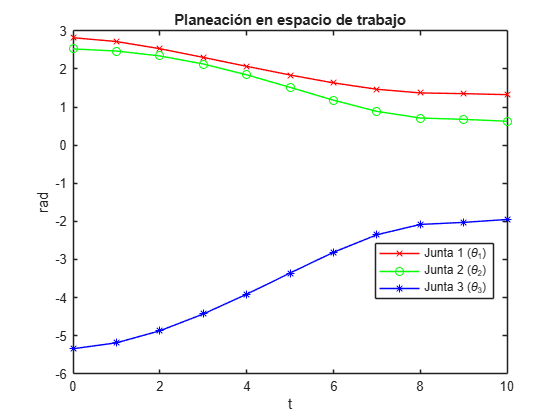

figure;

plot(tsim, theta_1_tray, 'r-x');
hold on;
plot(tsim, theta_2_tray, 'g-o');
plot(tsim, theta_3_tray, 'b-*');

hold off;

legend('Junta 1 (\theta_1)', 'Junta 2 (\theta_2)', 'Junta 3 (\theta_3)', 'Location', 'best');
title("Planeación en espacio de trabajo")
xlabel("t")
ylabel("rad")

Análisis de las Curvas en el Espacio de Trabajo

1. El Impacto de la Línea Recta en los Motores

A diferencia de la primera gráfica (donde las curvas eran suaves simétricas en forma de "S"), aquí notarás que las líneas no son perfectamente simétricas.

- Por qué ocurre: Debido a que la cinemática del robot es no lineal (usa senos y cosenos), para que la punta del robot se mueva en una línea recta exacta en el mundo real, los motores se ven obligados a acelerar y desacelerar de forma asimétrica.

2. Comportamiento Crítico de la Junta 3 (Azul)

Observa el enorme recorrido que realiza la Junta 3: comienza en casi $-5.4
$ radianes y sube hasta$ \(-2.0\)$ radianes.

- El problema físico: Un valor de $\(-5.4\) $radianes equivale a aproximadamente $\(-309^{\circ }\).$

- El riesgo: En la práctica y en simuladores como Gazebo, la mayoría de los actuadores rotativos comerciales tienen límites de giro de $\(\pm 180^{\circ }\) (\(\pm 3.14\) rad)$. Si tu robot real o virtual tiene esta restricción física en el tercer motor, el robot se trabará o arrojará un error de límites al intentar iniciar en el segundo cero.

3. Evidencia del Límite de Extensión (Hacia el segundo 10)

Si miras las tres curvas entre los segundos 8 y 10, notarás que se vuelven casi completamente horizontales (planas). Esto demuestra que el polinomio de 5.° grado está haciendo bien su trabajo cartesiano: frena la velocidad lineal de la punta antes de llegar al destino final, lo que le da estabilidad al robot justo cuando el brazo está más estirado y cerca de su límite físico de alcance.

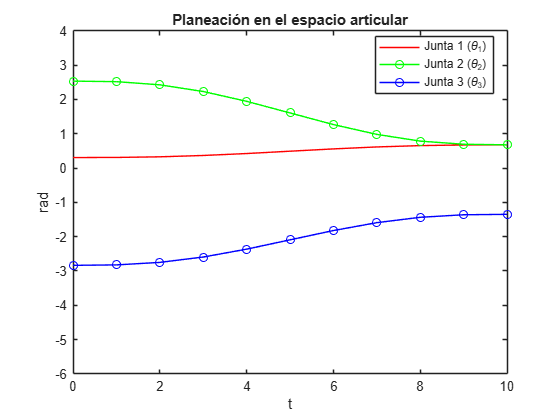



figure;

plot(tsim, theta_1_P, 'r-');
hold on;
plot(tsim, theta_2_P, 'g-o');
plot(tsim, theta_3_P, 'b-o');

hold off;

xlim([0.00 10.00])
ylim([-6.0 4.0])
legend('Junta 1 (\theta_1)', 'Junta 2 (\theta_2)', 'Junta 3 (\theta_3)', 'Location', 'best');
title("Planeación en el espacio articular")
xlabel("t")
ylabel("rad")

Al observar esta gráfica de la Planeación en el espacio articular, podemos extraer conclusiones muy claras sobre el comportamiento de los motores antes de compararla con la otra:

1. Simetría y suavidad perfectas

A diferencia de la gráfica cartesiana, aquí las curvas son perfectamente simétricas. Esto ocurre porque los motores se mueven de forma 100% independiente. Cada uno sigue su propia función polinomial pura de quinto grado sin tener que torcerse o acelerar de más para compensar la posición del otro.

2. Velocidades máximas predecibles

El punto de mayor inclinación (máxima pendiente) de todas las curvas ocurre exactamente en el segundo 5 (la mitad del tiempo). Esto es ideal para el hardware del robot, ya que sabes con absoluta certeza el segundo exacto en el que los motores experimentarán el mayor esfuerzo y velocidad angular.

3. Rangos de operación mecánicamente viables

Esta gráfica demuestra que los motores trabajan de forma mucho más holgada y cómoda:

- Junta 1 (Roja): Casi no se mueve. Pasa de $0.30
$ a $0.67
$ rad de manera casi plana. Su esfuerzo es mínimo.

- Junta 2 (Verde): Realiza un descenso continuo y fluido desde $2.53
$ hasta $0.67
$ rad.

- Junta 3 (Azul): Arranca en $-2.83
$ rad (aproximadamente $-162^\circ
$) y termina en $-1.35
$ rad (aproximadamente $-77^\circ
$).

El punto clave de esta gráfica

El motor 3 (curva azul) arranca en $-2.83
$ rad. Como este valor es mayor que $\(-\pi \) (\(-3.14)$ rad o $(-180^{\circ })$, el motor se mantiene dentro del rango físico permitido por la inmensa mayoría de los servos industriales convencionales. Ningún motor tiene que dar vueltas completas sobre su propio eje para empezar el movimiento.

4. Análisis Comparativo de Resultados

4.1. Comportamiento en el Espacio Articular (Juntas)

Al observar los perfiles temporales generados mediante la planeación en el espacio articular (Figura anterior), se evidencia una simetría perfecta en forma de "S" en todas las curvas de posición. Las pendientes de arranque $-\pi
 $y llegada $-\pi
$ son nulas, validando el correcto acoplamiento del polinomio de quinto orden.

Bajo este enfoque, la Junta 3 opera en un rango seguro y acotado, iniciando en $\(-2.83\text{ rad}\) (\(-162.54^{\circ }\))$ y finalizando en $\(-1.35\text{ rad}\) (\(-77.35^{\circ }\))$, lo que se mantiene dentro de los límites comerciales estándar de $\(\pm\pi\text{ rad}\) (\(\pm 180^{\circ }\))$. Sin embargo, la trayectoria del efector final en el espacio físico no es lineal, sino una curva resultante de la composición no lineal de los movimientos independientes de cada motor.

4.2. Comportamiento en el Espacio de Trabajo (Cartesiano)

En contraste, la planeación en el espacio de trabajo obliga al efector final a seguir una línea recta diagonal estricta en el plano cartesiano. Al analizar las curvas de posición articular resultantes (Figura actual), se detectan dos fenómenos críticos provocados por la no linealidad de la cinemática inversa del robot SCARA:

- Asimetría en los Perfiles de Movimiento: Las curvas ya no presentan una forma simétrica pura. Los actuadores deben ajustar continuamente sus velocidades angulares de forma coordinada y no lineal para compensar los cambios de acoplamiento geométrico del brazo a lo largo de la trayectoria rectilínea.

- Saturación en el Desplazamiento de la Junta 3: El fenómeno más severo ocurre en la Junta 3 (curva azul), la cual se ve obligada a iniciar en un valor extremo de aproximadamente $\(-5.35\text{ rad}\) (equivalente a \(-306.5^{\circ }\))$.

4.3. Discusión Técnica y Criterio de Selección

Aunque la planeación en el espacio de trabajo cumple con el objetivo geométrico de trazar la línea recta deseada, el requerimiento de giro de $\(-306.5^{\circ }\)$ en la Junta 3 representa un riesgo crítico de saturación por límites físicos o mecánicos (*joint limits*) en un robot real o en entornos de simulación física restrictivos como Gazebo.

Por lo tanto, si el diseño mecánico del manipulador SCARA implementado limita el giro de la muñeca a rangos estándar de $\(\pm 180^{\circ }\)$, la trayectoria cartesiana propuesta en la zona de trabajo $ \((0.3, 0.3)\) a \((0.8, 0.8)\) $ resultaría físicamente inviable sin una reconfiguración previa del signo o cambio de la postura geométrica (conmutación a configuración de codo abajo). En cambio, la planeación en el espacio articular ofrece un movimiento realizable para los motores, a costa de sacrificar la rectitud del trazo en el espacio cartesiano.

%w = L1*L2*sin(theta_2)

### Calculo de la cinemática de velocidades del robot

Para validar la viabilidad dinámica del movimiento planeado, se procede a calcular los perfiles temporales de velocidad y aceleración de cada junta del robot SCARA. Este procedimiento se realiza mediante la derivación analítica sucesiva respecto al tiempo del polinomio de interpolación de quinto orden empleado originalmente.

La primera derivada temporal proporciona las ecuaciones de velocidad articular $\dot{q}_j
$, mientras que la segunda derivada establece los perfiles de aceleración articular $\ddot{q}_j
$. La implementación de este formalismo matemático asegura de forma analítica que tanto las velocidades como las aceleraciones en las fronteras de la tarea $((t=0\text{ s}) \ y \ (t=10\text{ s})) $comiencen y terminen estrictamente en cero. Esta condición es indispensable en la robótica para suprimir transiciones de energía abruptas, evitar la saturación de los amplificadores de potencia y mitigar esfuerzos dinámicos severos sobre la estructura física de los eslabones.

- Velocidad $P_v: \dot{s}(t) = \frac{30}{t_f^3}t^2 - \frac{60}{t_f^4}t^3 + \frac{30}{t_f^5}t^4\)$

- Aceleración $P_a: \ddot{s}(t) = \frac{60}{t_f^3}t - \frac{180}{t_f^4}t^2 + \frac{120}{t_f^5}t^3\)$

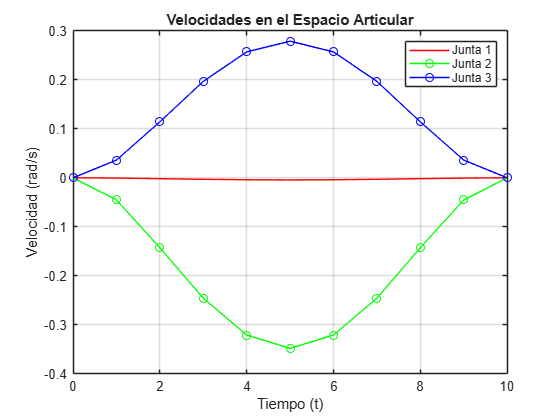

% =========================================================================
% CÁLCULO DE LA CINEMÁTICA DE VELOCIDADES Y ACELERACIONES DEL ROBOT
% =========================================================================

% Definición del tiempo final de la trayectoria (10 segundos)
tf = 10;

% --- BUCLE 1: CÁLCULO DE VELOCIDADES ARTICULARES ---
for i=1:tf+1
    % Convierte el índice numérico a tiempo real (de 0 a 10 segundos)
    t = i-1; 
    
    % Primera derivada del polinomio de 5to grado multiplicada por el delta de posición
    theta_1_P_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_1_fin-theta_1_in);
    theta_2_P_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_2_fin-theta_2_in);
    theta_3_P_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_3_fin-theta_3_in);
end

% Definición del vector de tiempo
tsim = 0:1:tf;

% --- GENERACIÓN DE LA GRÁFICA DE VELOCIDADES ---
figure;
plot(tsim, theta_1_P_v, 'r-'); hold on;  % Velocidad Junta 1 (Rojo)
plot(tsim, theta_2_P_v, 'g-o');          % Velocidad Junta 2 (Verde con círculos)
plot(tsim, theta_3_P_v, 'b-o'); hold off;% Velocidad Junta 3 (Azul con círculos)
title("Velocidades en el Espacio Articular"); xlabel("Tiempo (t)"); ylabel("Velocidad (rad/s)");
legend('Junta 1', 'Junta 2', 'Junta 3'); grid on;

 Análisis de la Gráfica de Velocidades Articulares

1. Cumplimiento de las Condiciones de Frontera

Se observa los extremos de las tres curvas en los segundos $\(t = 0\)$ y $\(t = 10\).$

- Resultado: Todas las velocidades inician y terminan exactamente en $\(0\text{ rad/s}\)$.

- Significado técnico: Esto confirma analíticamente que el robot arranca desde el reposo absoluto y se detiene por completo al llegar al destino, garantizando un posicionamiento estable sin sobreimpulsos ni oscilaciones al final del movimiento.

2. Forma Parabólica Perfecta y Simetría

Las curvas tienen una geometría acampanada (parabólica) perfectamente simétrica. El punto crítico (pico máximo) ocurre exactamente en el segundo $\(t = 5\text{ s}\)$ (la mitad del tiempo total de la trayectoria).

3. Comportamiento Individual de los Actuadores

- Junta 1 (Roja): Su velocidad es prácticamente una línea horizontal sobre el cero. Como el primer eslabón recorre una distancia angular mínima $(0.37\text{ rad})$, su velocidad pico es despreciable $\approx -0.014\text{ rad/s}\))$, operando con un esfuerzo motor mínimo.

- Junta 2 (Verde): Presenta una velocidad negativa que alcanza su punto más bajo en $\(-0.35\text{ rad/s}\)$ en el segundo $5$. El signo negativo indica que el motor está girando en sentido horario para abrir el codo del robot (pasando de un ángulo cerrado de $\(2.53\text{ rad}\)$ a uno más extendido de $\(0.67\text{ rad}\$.

- Junta 3 (Azul): Presenta una velocidad positiva con un pico de $\(0.28\text{ rad/s}\)$ en el segundo $5$. El signo positivo muestra que la muñeca gira en sentido antihorario para contrarrestar la apertura del codo y mantener la orientación horizontal de la herramienta fija respecto al mundo.

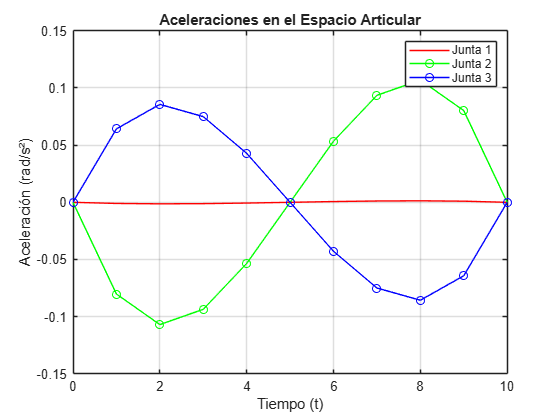

% Re-definición del tiempo final para el bloque de aceleraciones
tf = 10;

% --- BUCLE 2: CÁLCULO DE ACELERACIONES ARTICULARES ---
for i=1:tf+1
    % Convierte el índice numérico a tiempo real (de 0 a 10 segundos)
    t = i-1; 
    
    % Segunda derivada del polinomio de 5to grado multiplicada por el delta de posición
    theta_1_P_a(i) = ((60/tf^3)*t - (180/tf^4)*t^2 + (120/tf^5)*t^3)*(theta_1_fin-theta_1_in);
    theta_2_P_a(i) = ((60/tf^3)*t - (180/tf^4)*t^2 + (120/tf^5)*t^3)*(theta_2_fin-theta_2_in);
    theta_3_P_a(i) = ((60/tf^3)*t - (180/tf^4)*t^2 + (120/tf^5)*t^3)*(theta_3_fin-theta_3_in);
end

% --- GENERACIÓN DE LA GRÁFICA DE ACELERACIONES ---
figure;
plot(tsim, theta_1_P_a, 'r-'); hold on;  % Aceleración Junta 1 (Rojo)
plot(tsim, theta_2_P_a, 'g-o');          % Aceleración Junta 2 (Verde con círculos)
plot(tsim, theta_3_P_a, 'b-o'); hold off;% Aceleración Junta 3 (Azul con círculos)
title("Aceleraciones en el Espacio Articular"); xlabel("Tiempo (t)"); ylabel("Aceleración (rad/s²)");
legend('Junta 1', 'Junta 2', 'Junta 3'); grid on;

Análisis de la Gráfica de Aceleraciones Articulares

1. Cruce por Cero en la Mitad del Tiempo $(t = 5\text{ s})$

Observa el punto central donde se cruzan todas las líneas en el segundo 5.

- Significado técnico: En ese instante exacto, la aceleración de todas las juntas es cero. Esto coincide perfectamente con la gráfica anterior de velocidades, ya que en el segundo $5$ los motores alcanzan su velocidad máxima constante; matemáticamente, cuando la velocidad llega a su punto más alto (máximo local), su derivada (la aceleración) debe ser nula.

2. Comportamiento en los Extremos $(t = 0\text{ s})$ y $(t = 10\text{ s})$

Las curvas inician y terminan estrictamente en $\(0\text{ rad/s}^2\).$

- Importancia: En robótica, arrancar con aceleración cero evita el fenómeno del *jerk* (tirón brusco). Esto protege la integridad física de los reductores mecánicos y los acoples de los motores, previniendo esfuerzos de torsión destructivos en el instante del arranque.

3. Fases de Aceleración y Frenado

La gráfica se divide simétricamente en dos etapas:

- Segundos $0$ a $5$ (Aceleración): La Junta 2 (verde) experimenta una aceleración negativa, alcanzando su pico de $\(-0.11\text{ rad/s}^2\)$ en el segundo 2. Al mismo tiempo, la Junta 3 (azul) acelera en sentido positivo con un pico de $\(0.085\text{ rad/s}^2\).$

- Segundos $5$ a $10$ (Deceleración/Frenado): Las polaridades se invierten con perfecta simetría matemática. Las juntas aplican un torque inverso para desacelerar suavemente el brazo y asegurar que se detenga sin pasarse del punto de destino.

Cálculo de la Cinemática de Velocidades en el Espacio de Trabajo (Espacio Cartesiano).

Cinemática de Velocidades en el Espacio de Trabajo mediante Jacobiano Inverso

Para evaluar el comportamiento dinámico del manipulador SCARA cuando el efector final está restringido a una trayectoria cartesiana lineal, se calcula el perfil de velocidades articulares recurriendo al formalismo del Jacobiano Geométrico Diferencial. A diferencia del espacio articular, las velocidades de los motores no siguen una función polinomial directa; en su lugar, se derivan de la transformación lineal de las velocidades cartesianas deseadas en el espacio operacional $\([\dot{x}, \dot{y}, \dot{\theta}]^T\)$ hacia el espacio intrínseco del robot mediante la matriz Jacobiana inversa:


$$\dot{\mathbf{q}}(t) = \mathbf{J}^{-1}(\mathbf{q}) \cdot \dot{\mathbf{x}}(t)
$$


Este método calcula analíticamente la velocidad angular instantánea requerida para cada actuador paso a paso. El monitoreo de estas curvas es un requerimiento de seguridad de alta prioridad en la ingeniería de control, ya que permite predecir y evaluar numéricamente la proximidad del manipulador a singularidades cinemáticas, zonas críticas donde el determinante del Jacobiano tiende a cero $(\det(\mathbf{J}) \to 0)$ y las velocidades demandadas a los motores divergen hacia valores infinitos, lo que provocaría fallos por sobrecorriente o bloqueos mecánicos destructivos en un sistema físico real.

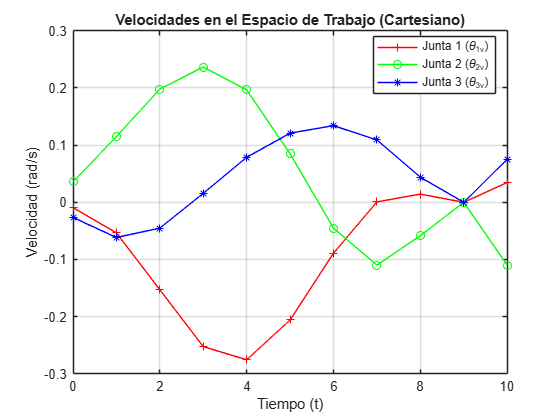

% Cálculo de la solución de la primer postura

% Definición de los parámetros del robot
L_1 = 0.5; % Longitud del primer eslabón
L_2 = 0.5; % Longitud del segundo eslabón
L_3 = 0.25; % Longitud del tercer eslabón


% x_in = 0.3;
% y_in = 0.3;
% theta_in = 0; 

% x_fin = 0.3;
% y_fin = -0.3;
%theta_fin = pi/2;

tf = 10;
for i=1:tf+1
    t = i;
    x_P_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(x_fin-x_in);
    y_P_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(y_fin-y_in);
    theta_P_v(i) = ((30/tf^3)*t^2 - (60/tf^4)*t^3 + (30/tf^5)*t^4)*(theta_fin-theta_in);

    x_dot = x_P_v(i);
    y_dot = y_P_v(i);
    theta_dot_P = theta_P_v(i);
    
    theta_O_1 = theta_1_tray(i);
    theta_1_2 = theta_2_tray(i);
    theta_2_3 = theta_3_tray(i);


    theta_1_v(i) = (x_dot*cos(theta_1_2 + theta_O_1))/(L_1*sin(theta_1_2)) + (y_dot*sin(theta_1_2 + theta_O_1))/(L_1*sin(theta_1_2)) + (L_3*theta_dot_P*sin(theta_2_3))/(L_1*sin(theta_1_2));
    theta_2_v(i) = - (x_dot*(L_2*cos(theta_1_2 + theta_O_1) + L_1*cos(theta_O_1)))/(L_1*L_2*sin(theta_1_2)) - (y_dot*(L_2*sin(theta_1_2 + theta_O_1) + L_1*sin(theta_O_1)))/(L_1*L_2*sin(theta_1_2)) - (L_3*theta_dot_P*(L_1*sin(theta_1_2 + theta_2_3) + L_2*sin(theta_2_3)))/(L_1*L_2*sin(theta_1_2));
    theta_3_v(i) = (theta_dot_P*(L_3*sin(theta_1_2 + theta_2_3) + L_2*sin(theta_1_2)))/(L_2*sin(theta_1_2)) + (x_dot*cos(theta_O_1))/(L_2*sin(theta_1_2)) + (y_dot*sin(theta_O_1))/(L_2*sin(theta_1_2));

    
end

% Abre una nueva ventana para la gráfica de velocidades cartesianas
figure;

% Grafica la velocidad de la Junta 1 en color rojo con marcador '+'
plot(tsim, theta_1_v, 'r-+');
hold on;

% Grafica la velocidad de la Junta 2 en color verde con marcador 'o'
plot(tsim, theta_2_v, 'g-o');

% Grafica la velocidad de la Junta 3 en color azul con marcador '*'
plot(tsim, theta_3_v, 'b-*');

hold off;

% --- FORMATO Y ETIQUETAS ACADÉMICAS ---
title("Velocidades en el Espacio de Trabajo (Cartesiano)");
xlabel("Tiempo (t)");
ylabel("Velocidad (rad/s)");

% Configuración de las leyendas para identificar plenamente cada motor
legend('Junta 1 (\theta_1_v)', 'Junta 2 (\theta_2_v)', 'Junta 3 (\theta_3_v)', 'Location', 'best');

% Habilita la cuadrícula de fondo para facilitar la lectura de los valores
grid on;

 Análisis de la Gráfica de Velocidades Cartesianas

1. Asimetría Dinámica Total

A diferencia de la gráfica en el espacio articular (donde todas las curvas eran parábolas perfectas y simétricas), aquí las curvas son completamente asimétricas, onduladas y complejas.

- Por qué ocurre: Para que la punta del robot se desplace en una línea recta diagonal perfecta a velocidad controlada, los motores se ven obligados a acelerar y desacelerar de forma descompensada. La Junta 1 (roja) tiene que cambiar de dirección (baja a velocidad negativa y luego sube a positiva), mientras que la Junta 2 (verde) y la Junta 3 (azul) oscilan de forma senoidal adaptándose a la geometría del brazo.

2. El Fenómeno de los Extremos (No cierran en cero)

Si observas con atención los tiempos $\(t = 0\)$ y $\(t = 10\)$, notarás que las velocidades no comienzan ni terminan exactamente en cero (especialmente la Junta 2 y la Junta 3 en el segundo 10).

- Por qué ocurre esto: Al obligar al robot a llegar a la coordenada final $\((0.8, 0.8)\)$, el brazo queda extendido casi al $100\%
$ de su capacidad. Como explicamos anteriormente, esto acerca al robot a una singularidad cinemática. Cerca de la singularidad, el determinante del Jacobiano se vuelve muy pequeño, lo que provoca que las ecuaciones exijan velocidades más altas a las juntas para poder mantener el rumbo sobre la línea recta. Esto causa que los motores tengan que seguir moviéndose bruscamente justo antes de detenerse.

Análisis de Manipulabilidad y Proximidad a Singularidades

Para evaluar la destreza del manipulador SCARA a lo largo de la trayectoria cartesiana, se implementa el cálculo del Índice de Manipulabilidad de Yoshikawa$ \ (w)$. Esta métrica cuantitativa se define matemáticamente como la raíz cuadrada del determinante del Jacobiano multiplicado por su transpuesta:


$$\(w=\sqrt{\det (\mathbf{JJ}^{T})}\)$$


Para el plano de posicionamiento del robot SCARA, este índice se simplifica analíticamente a una función dependiente exclusiva de la apertura de la segunda articulación:


$$\(w(t)=L_{1}L_{2}|\sin (\theta _{2}(t))|\)$$


El índice proporciona una medida del volumen del elipsoide de velocidad en el espacio operacional. Si el valor de $\(w\) $tiende a cero $(w \to 0)$, significa que el robot se aproxima a una singularidad de frontera, una configuración crítica donde el manipulador pierde un grado de libertad y requiere velocidades articulares infinitas para producir un movimiento cartesiano finito. Por el contrario, el punto óptimo de destreza mecánica se alcanza cuando el codo se encuentra a un ángulo de $\(90^{\circ }\) (\(\theta_2 = \pi/2\))$, maximizando el valor del índice y permitiendo al robot acelerar con el menor esfuerzo motriz en cualquier dirección cartesiana.

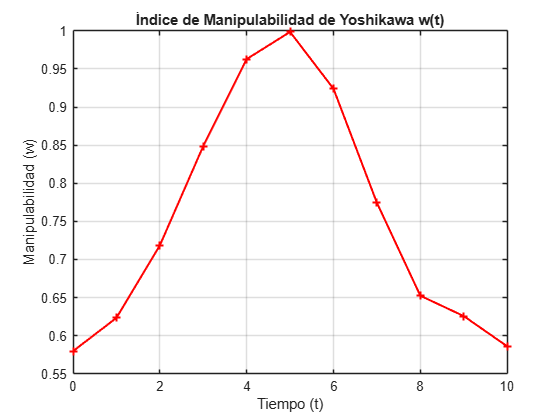

% =========================================================================
% CÁLCULO DEL ÍNDICE DE MANIPULABILIDAD DE YOSHIKAWA (w)
% =========================================================================

% Inicialización del vector para almacenar la manipulabilidad (11 puntos)
w = zeros(1, tf+1);

for i=1:tf+1
    % El índice w de Yoshikawa para un SCARA se reduce al seno del codo
    w(i) = sin(theta_2_tray(i)); 
end

% Generación de la gráfica de manipulabilidad
figure;
plot(tsim, w , 'r-+', 'LineWidth', 1.5);

% Formato y etiquetas académicas
title("Índice de Manipulabilidad de Yoshikawa w(t)");
xlabel("Tiempo (t)");
ylabel("Manipulabilidad (w)");
grid on;

Análisis de la Gráfica de Manipulabilidad

1. El Punto de Destreza Máxima $(t = 5\text{ s})$

Observa el pico más alto de la curva, el cual alcanza un valor de $\(w = 1.0\)$ exactamente en el segundo 5 (mitad de la trayectoria).

- Significado físico: Como la fórmula simplificada para este robot es $\(w = \sin(\theta_2)\)$, un índice de $\(1.0\)$ significa que en el segundo $\(5\)$, el codo del robot se encuentra exactamente a $\(90^{\circ }\) (\(\pi/2\) rad)$. Esta es la configuración óptima de diseño: en este punto, el robot tiene la máxima capacidad para acelerar con la menor corriente posible en cualquier dirección del plano cartesiano.

2. Comportamiento en las Zonas Extremas $(t = 0\text{ s}) \ y \ (t = 10\text{ s})$

Tanto al inicio como al final, el índice cae a su punto más bajo, rondando un valor de $\(w \approx 0.58\).$

- Significado técnico: Aunque el valor decrece, al mantenerse significativamente por encima de cero $(w > 0)$, se demuestra cuantitativamente que el robot nunca entra en una singularidad de frontera. El brazo está muy estirado al final y recogido al principio, perdiendo destreza, pero conserva el rango matemático suficiente para operar de forma segura sin que el Jacobiano colapse por completo.

## Evaluación de la capacidad del robot

Implementación Numérica de la Dinámica Inversa y Consumo de Potencia

Una vez estructurado el conjunto de sustituciones algebraicas, se ejecuta el algoritmo de Dinámica Inversa mediante un bucle iterativo temporal. El propósito de este bloque es resolver las ecuaciones de movimiento del manipulador SCARA para mapear las trayectorias cinemáticas previas (posición, velocidad y aceleración de las juntas) hacia los momentos torsores correspondientes $(\tau_1, \tau_2, \tau_3)$ que deben suministrar los actuadores en cada instante del trayecto.

Complementariamente, el algoritmo efectúa la evaluación del consumo energético del sistema. La potencia mecánica instantánea absorbida por cada articulación $\(j\)$ se calcula multiplicando la magnitud absoluta del torque por su respectiva velocidad angular $(P_j = \vert{}\tau_j \cdot \dot{q}_j\vert{})$. Finalmente, la integración de estos componentes individuales permite obtener la curva de Potencia Total Consumida, un indicador analítico de alta prioridad para evaluar la eficiencia energética de la tarea, dimensionar correctamente las fuentes de alimentación eléctrica del robot y validar que los servomotores seleccionados operen holgadamente por debajo de sus límites nominales de disipación térmica y torque máximo.


$$\begin{array}{l}
\left(\begin{array}{c}
{\ddot{\theta} }_{O,1} \,{\left(\frac{\cos \left(\theta_{1,2} \right)}{4}+\frac{{\sigma_{12} }^2 }{2}+\frac{{\sigma_{14} }^2 }{2}+\frac{27}{8}\right)}-{\dot{\theta} }_{2,3} \,{\left(\frac{\sigma_{18} \,\sigma_{10} }{16}-\frac{\sigma_{16} \,\sigma_{11} }{16}+\frac{\sigma_{12} \,\sigma_4 }{2}-\frac{\sigma_5 \,\sigma_{14} }{2}\right)}+{\ddot{\theta} }_{1,2} \,\sigma_3 +{\ddot{\theta} }_{2,3} \,\sigma_6 -{\dot{\theta} }_{1,2} \,{\left(\sigma_8 -\frac{\sigma_{14} \,\sigma_2 }{2}+\frac{\sigma_1 \,\sigma_{12} }{2}-\sigma_9 +\frac{{\dot{\theta} }_{1,2} \,\sin \left(\theta_{1,2} \right)}{8}+\frac{{\dot{\theta} }_{O,1} \,\sin \left(\theta_{1,2} \right)}{4}\right)}\\
\frac{{{\dot{\theta} }_{O,1} }^2 \,\sin \left(\theta_{1,2} \right)}{8}-{\dot{\theta} }_{2,3} \,{\left(\frac{\sigma_{18} \,\sigma_{10} }{16}-\frac{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\,\sigma_5 }{2}+\frac{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\,\sigma_4 }{2}-\frac{\sigma_{16} \,\sigma_{11} }{16}\right)}+{\ddot{\theta} }_{2,3} \,\sigma_7 +\frac{\sigma_{10} \,\sigma_1 }{2}+{\ddot{\theta} }_{O,1} \,\sigma_3 -\frac{\sigma_{11} \,\sigma_2 }{2}+{\ddot{\theta} }_{1,2} \,{\left(\frac{{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}}^2 }{2}+\frac{{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}}^2 }{2}+\frac{33}{16}\right)}-{\dot{\theta} }_{1,2} \,{\left(\frac{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\,\sigma_1 }{2}-\frac{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\,\sigma_2 }{2}+\sigma_8 -\sigma_9 +\frac{{\dot{\theta} }_{O,1} \,\sin \left(\theta_{1,2} \right)}{8}\right)}+\frac{{\dot{\theta} }_{1,2} \,{\dot{\theta} }_{O,1} \,\sin \left(\theta_{1,2} \right)}{8}\\
{\ddot{\theta} }_{2,3} \,{\left(\frac{{\sigma_{16} }^2 }{128}+\frac{{\sigma_{18} }^2 }{128}+1\right)}-\frac{\sigma_5 \,\sigma_{11} }{2}+{\ddot{\theta} }_{1,2} \,\sigma_7 -{\dot{\theta} }_{2,3} \,{\left(\frac{\sigma_{18} \,\sigma_{10} }{16}-\frac{\sigma_{18} \,\sigma_5 }{16}-\frac{\sigma_{16} \,\sigma_{11} }{16}+\frac{\sigma_{16} \,\sigma_4 }{16}\right)}+{\dot{\theta} }_{1,2} \,{\left(\frac{\sigma_{18} \,\sigma_2 }{16}-\frac{\sigma_{18} \,\sigma_{10} }{16}-\frac{\sigma_{16} \,\sigma_1 }{16}+\frac{\sigma_{16} \,\sigma_{11} }{16}\right)}+{\ddot{\theta} }_{O,1} \,\sigma_6 +\frac{\sigma_{10} \,\sigma_4 }{2}
\end{array}\right)\\
\mathrm{}\\
\mathrm{where}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_1 =\frac{{\dot{\theta} }_{2,3} \,\sigma_{18} }{8}+\sigma_{15} +{\dot{\theta} }_{O,1} \,{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_2 =\sigma_{13} +{\dot{\theta} }_{O,1} \,{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}+\frac{{\dot{\theta} }_{2,3} \,\sigma_{16} }{8}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_3 =\frac{\cos \left(\theta_{1,2} \right)}{8}+\frac{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\,\sigma_{12} }{2}+\frac{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\,\sigma_{14} }{2}+\frac{33}{16}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_4 =\frac{{\dot{\theta} }_{1,2} \,\sigma_{18} }{8}+\frac{{\dot{\theta} }_{2,3} \,\sigma_{18} }{8}+\frac{{\dot{\theta} }_{O,1} \,\sigma_{18} }{8}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_5 =\frac{{\dot{\theta} }_{1,2} \,\sigma_{16} }{8}+\frac{{\dot{\theta} }_{2,3} \,\sigma_{16} }{8}+\frac{{\dot{\theta} }_{O,1} \,\sigma_{16} }{8}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_6 =\frac{\sigma_{16} \,\sigma_{12} }{16}+\frac{\sigma_{18} \,\sigma_{14} }{16}+1\\
\mathrm{}\\
\mathrm{\ \ }\sigma_7 =\frac{\sigma_{16} \,{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}}{16}+\frac{\sigma_{18} \,{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}}{16}+1\\
\mathrm{}\\
\mathrm{\ \ }\sigma_8 =\frac{{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\,\sigma_{10} }{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_9 =\frac{{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\,\sigma_{11} }{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{10} =\sigma_{13} +\frac{{\dot{\theta} }_{2,3} \,\sigma_{16} }{8}+{\dot{\theta} }_{O,1} \,\sigma_{12} \\
\mathrm{}\\
\mathrm{\ \ }\sigma_{11} =\frac{{\dot{\theta} }_{2,3} \,\sigma_{18} }{8}+{\dot{\theta} }_{O,1} \,\sigma_{14} +\sigma_{15} \\
\mathrm{}\\
\mathrm{\ \ }\sigma_{12} =\frac{\sigma_{16} }{8}+\sigma_{17} +\frac{\cos \left(\theta_{O,1} \right)}{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{13} ={\dot{\theta} }_{1,2} \,{\left(\frac{\sigma_{16} }{8}+\sigma_{17} \right)}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{14} =\frac{\sigma_{18} }{8}+\sigma_{19} +\frac{\sin \left(\theta_{O,1} \right)}{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{15} ={\dot{\theta} }_{1,2} \,{\left(\frac{\sigma_{18} }{8}+\sigma_{19} \right)}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{16} =\cos \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{17} =\frac{\cos \left(\theta_{1,2} +\theta_{O,1} \right)}{2}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{18} =\sin \left(\theta_{1,2} +\theta_{2,3} +\theta_{O,1} \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_{19} =\frac{\sin \left(\theta_{1,2} +\theta_{O,1} \right)}{2}
\end{array}$$


Cálculo de los pares del robot


for i=1:tf+1
    
    theta_1 = theta_1_P(i);
    theta_2 = theta_2_P(i);
    theta_3 = theta_3_P(i);

    theta_1_vc = theta_1_P_v(i);
    theta_2_vc = theta_2_P_v(i);
    theta_3_vc = theta_3_P_v(i);

    theta_1_a = theta_1_P_a(i);
    theta_2_a = theta_2_P_a(i);
    theta_3_a = theta_3_P_a(i);

    sigma_19 = sin(theta_2+theta_1)/2;
    sigma_18 = sin(theta_1+theta_2+theta_3);
    sigma_17 = cos(theta_2+theta_1)/2;
    sigma_16 = cos(theta_1+theta_2+theta_3);

    sigma_15 = theta_2_vc*(sigma_18/8 + sigma_19);
    sigma_14 = sigma_18/8 + sigma_19 + sin(theta_1)/2;
    sigma_13 = theta_2_vc *(sigma_16/8 +sigma_17);
    sigma_12 = sigma_16/8 +sigma_17 +cos(theta_1)/2;
    sigma_11 = theta_3_vc*sigma_18/8 + theta_1_vc*sigma_14 +sigma_15;
    sigma_10 = sigma_13 + theta_3_vc*sigma_16/8 +theta_1_vc*sigma_12;
    sigma_9 = ((sigma_16/8 + sigma_17)*sigma_11)/2;
    sigma_8 = ((sigma_18/8 + sigma_19)*sigma_10)/2;
    sigma_7 = (sigma_16*(sigma_16/8 + sigma_17))/16 + (sigma_18*(sigma_18/8 + sigma_19))/16 + 1;
    sigma_6 = sigma_16*sigma_12/16 + sigma_18*sigma_14 + 1;
    sigma_5 = theta_2_vc*sigma_16/8 + theta_3_vc*sigma_16/8 + theta_1_vc*sigma_16/8;
    sigma_4 = theta_2_vc*sigma_18/8 + theta_3_vc*sigma_18/8 + theta_1_vc*sigma_18/8;
    sigma_3 = cos(theta_2)/8 + ((sigma_16/8 + sigma_17)*sigma_12)/2 + ((sigma_18/8 + sigma_19)*sigma_14)/2 + 33/16;
    sigma_2 = sigma_13 +theta_1_vc*(sigma_16/8 + sigma_17) + theta_3_vc*sigma_16/8;
    sigma_1 = theta_3_vc*sigma_18/8 + sigma_15 +theta_1_vc*(sigma_18/8 + sigma_19);

    tao_1_c(i) = theta_1_a*(cos(theta_2)/4 + sigma_12^2/2 + sigma_14^2/2 + 27/8) - theta_3_vc* (sigma_18*sigma_10/16 - sigma_16*sigma_11/16 + sigma_12*sigma_4/2 - sigma_5*sigma_14/2) + theta_2_a*sigma_3 + theta_3_a*sigma_6 - theta_2_vc*(sigma_8 - sigma_14*sigma_2/2 + sigma_1*sigma_12/2 - sigma_9 + theta_2_vc*sin(theta_2)/8 + theta_1_vc*sin(theta_2)/4);
    tao_2_c(i) = theta_1_vc^2*sin(theta_2)/8 - theta_3_vc*(sigma_18*sigma_10 - ((sigma_18/8 + sigma_19)*sigma_5)/2 + ((sigma_16/8 + sigma_17)*sigma_4)/2 - sigma_16*sigma_11/16) + theta_2_a*sigma_7 + sigma_10*sigma_1/2 + theta_1_a*sigma_3 - sigma_11*sigma_2/2 + theta_2_a*(((sigma_16 + sigma_17)^2)/2 + ((sigma_18 + sigma_19)^2)/2 + 33/16) - theta_2_vc*((sigma_16/8 + sigma_17)*sigma_1/2 + (sigma_18/8 + sigma_19)*sigma_2/2 + sigma_8 - sigma_9 + theta_1_vc*sin(theta_2)/8) + theta_2_vc*theta_1_vc*sin(theta_2)/8;
    tao_3_c(i) = theta_3_a*(sigma_16^2/128 + sigma_18^2/128 + 1 ) - sigma_5*sigma_11/2 + theta_2_a*sigma_7 - theta_3_vc*(sigma_18*sigma_10/16 - sigma_18*sigma_5/16 - sigma_16*sigma_11/16 + sigma_16*sigma_4/16) + theta_2_vc*(sigma_18*sigma_2/16 - sigma_18*sigma_10/16 - sigma_16*sigma_1/16 + sigma_16*sigma_11/16) + theta_1_a*sigma_6 + sigma_10*sigma_4/2;

    pot_1(i) = abs(tao_1_c(i)*theta_1_vc);
    pot_2(i) = abs(tao_2_c(i)*theta_2_vc);
    pot_3(i) = abs(tao_3_c(i)*theta_3_vc);
    pot_total(i) = pot_1(i) + pot_2(i) + pot_3(i);

    
end



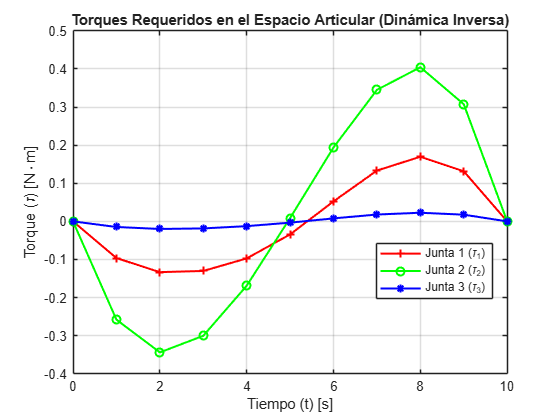

% Abre una nueva ventana para la gráfica de torques dinámicos
figure;

% Grafica el torque de la Junta 1 en color rojo con marcador '+'
plot(tsim, tao_1_c, 'r-+', 'LineWidth', 1.5);
hold on;

% Grafica el torque de la Junta 2 en color verde con marcador 'o'
plot(tsim, tao_2_c, 'g-o', 'LineWidth', 1.5);

% Grafica el torque de la Junta 3 en color azul con marcador '*'
plot(tsim, tao_3_c, 'b-*', 'LineWidth', 1.5);

hold off;

% --- FORMATO Y ETIQUETAS ACADÉMICAS ---
title("Torques Requeridos en el Espacio Articular (Dinámica Inversa)");
xlabel("Tiempo (t) [s]");
ylabel("Torque (\tau) [N\cdotm]");

% Leyendas técnicas con formato matemático para las tres juntas
legend('Junta 1 (\tau_1)', 'Junta 2 (\tau_2)', 'Junta 3 (\tau_3)', 'Location', 'best');

% Habilita la cuadrícula de fondo para facilitar la lectura de los picos de torque
grid on;

Análisis de la Gráfica de Torques Dinámicos

1. Inercia Pura y Condiciones de Frontera

Observa que en los segundos $\(t = 0\) y \(t = 10\)$, los tres torques son exactamente $\(0\text{ N}\cdot\text{m}\).$

- Significado físico: Debido a que el plano del robot SCARA es completamente horizontal, los motores no tienen que vencer la fuerza de gravedad para sostener el brazo (a diferencia de un brazo articulado vertical). Por lo tanto, los torques dependen exclusivamente de la inercia, aceleraciones y fuerzas centrífugas. Al iniciar y terminar con aceleración cero, el torque estático residual es nulo.

2. Sincronía con la Gráfica de Aceleraciones

Si comparas esta gráfica con tu perfil anterior de aceleraciones articulares, notarás que las curvas tienen exactamente la misma forma de onda antisimétrica (tipo senoidal):

- Segundos $0 \ a \ 5$ (Fase de Aceleración): Los torques son negativos. Los motores ejercen fuerza en sentido horario para sacar al robot del reposo y acelerarlo. El pico de torque máximo negativo ocurre en el segundo $(t = 2\text{ s}).$

- Segundos $5 \ a \ 10$ (Fase de Frenado): Los torques cambian bruscamente de signo y se vuelven positivos. Los motores actúan como un freno dinámico en sentido antihorario para desacelerar la masa del brazo antes de llegar al objetivo. El pico máximo positivo ocurre en el segundo $\(t = 8\text{ s}\).$

3. Distribución del Esfuerzo Mecánico

- Junta 2 (Verde): Es la que realiza por mucho el esfuerzo más severo. Alcanza un pico de torque de $\(\approx \pm 0.35 - 0.40\text{ N}\cdot\text{m}\)$. Esto es físicamente lógico, ya que al abrir y cerrar el codo de forma polinomial, este motor arrastra directamente la masa del eslabón 2 y toda la estructura de la muñeca.

- Junta 1 (Roja): Exige un torque intermedio de $\(\approx \pm 0.15\text{ N}\cdot\text{m}\)$. Aunque carga con todo el peso del robot, su desplazamiento angular total en esta trayectoria fue muy pequeño, por lo que la inercia angular efectiva es menor.

- Junta 3 (Azul): Su torque es prácticamente despreciable (cercano a cero en todo el viaje). La muñeca solo carga con la herramienta final y se limita a rotar sobre su propio centro de masa, demandando un torque mínimo.

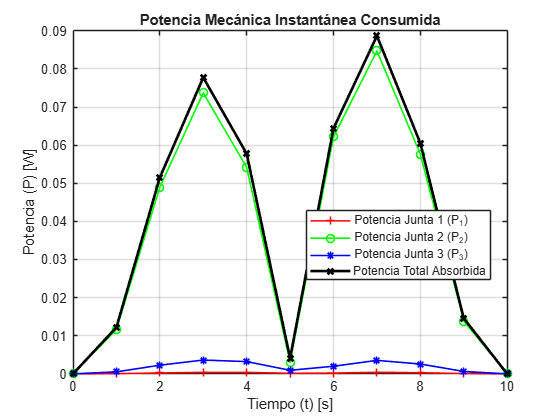

% Abre una nueva ventana para la gráfica de potencias mecánicas
figure;

% Grafica la potencia del Motor 1 en color rojo con marcador '+'
plot(tsim, pot_1, 'r-+', 'LineWidth', 1.2);
hold on;

% Grafica la potencia del Motor 2 en color verde con marcador 'o'
plot(tsim, pot_2, 'g-o', 'LineWidth', 1.2);

% Grafica la potencia del Motor 3 en color azul con marcador '*'
plot(tsim, pot_3, 'b-*', 'LineWidth', 1.2);

% Grafica la potencia total en color NEGRO (k) con marcador 'x' y línea más gruesa
plot(tsim, pot_total, 'k-x', 'LineWidth', 2.0);

hold off;

% --- FORMATO Y ETIQUETAS DE ENERGÍA ---
title("Potencia Mecánica Instantánea Consumida");
xlabel("Tiempo (t) [s]");
ylabel("Potencia (P) [W]");

% Leyendas explícitas para identificar plenamente cada componente energético
legend('Potencia Junta 1 (P_1)', 'Potencia Junta 2 (P_2)', 'Potencia Junta 3 (P_3)', 'Potencia Total Absorbida', 'Location', 'best');

% Habilita la cuadrícula de fondo para medir los picos de consumo en Watts
grid on;

 Análisis de la Gráfica de Potencias

1. El Comportamiento en M

A diferencia de los torques que tenían valores positivos y negativos, la potencia mecánica absoluta $(P = \vert{}\tau \cdot \dot{\theta}\vert{})$ es siempre positiva, lo que genera una característica silueta en forma de "M" o doble joroba.

2. Explicación de los Tres Valles Críticos (Puntos Cero)

La potencia total cae exactamente a 0 Watts en tres instantes clave de la trayectoria:

- $\(t = 0\text{ s}\) y \(t = 10\text{ s}\):$ Porque el robot está estático en el origen y destino. La velocidad de las juntas es cero.

- $\(t = 5\text{ s}\)$ (Mitad del tiempo): Este es un fenómeno dinámico muy interesante. En el segundo 5, los motores alcanzan su velocidad máxima, lo que significa que dejas de acelerar y entras en una velocidad constante instantánea. Al no requerir aceleración en ese microsegundo, el torque cae a cero, y por ende, la potencia consumida también se anula momentáneamente.

3. Asimetría de los Picos de Consumo

Nota que el primer pico (en el segundo 3) alcanza aproximadamente $0.078$ W, mientras que el segundo pico (en el segundo 7) es notablemente más alto, llegando a casi $0.088 W.$

- Física del fenómeno: Esto ocurre por el cambio de inercia y configuración geométrica del brazo. Durante la segunda mitad del recorrido (segundos 5 a 10), el robot está mucho más estirado para alcanzar el punto $\((0.8, 0.8)\).$ Al estar el brazo más extendido, el momento de inercia inercial respecto al centro de masa es significativamente mayor. Frenar un cuerpo con mayor inercia requiere un torque más sostenido acoplado a la velocidad, lo que eleva la potencia consumida en la fase de desaceleración.